# Center a molecule

Import a structure and center it

close all;
atom=import_atom('6x4MMT_x10y5z0.gro'); % A non-centered structure

Found .gro file
.gro file imported
Elapsed time is 0.014546 seconds.
Looking up bonds
Calculating the distance matrix


ans = 1×1 cell array
    {'Al'}

ans = 1×1 cell array
    {'H'}

ans = 1×1 cell array
    {'O'}

ans = 1×1 cell array
    {'Si'}

ans =    960

Composition info:


composition = struct with fields:
     resnames: {'MMT'}
    nresidues: 1
       natoms: 960

Atom_types = 1×4 cell array
    {'Al'}    {'H'}    {'O'}    {'Si'}

Atom_numbers =     96    96   576   192


The box dimensions are:


Box_dim =   31.187999999999999  36.060000000000002  10.000000000000000


The cell dimensions are:


Cell =   31.187999999999999  36.060000000000002  10.000000000000000  90.000000000000000  90.000000000000000  90.000000000000000


atom=center_atom(atom,Box_dim); % This will also replicate Box_dim

Centering
centering along x
centering along y
centering along z


ans =   -0.005000000000000

Choose between these representations:
ballstick licorice smallvdw halfvdw vdw contour crystal ionic polyhedra lines labels charge index


rmaxlong =    2.250000000000000

Scanning intramolecular bonds, neglecting the PBC
Calculating the distance matrix


ans = 1×1 cell array
    {'Al'}

ans = 1×1 cell array
    {'H'}

ans = 1×1 cell array
    {'O'}

ans = 1×1 cell array
    {'Si'}

ans =    960

Elapsed time is 0.332066 seconds.
Drawing the atoms
Elapsed time is 0.227230 seconds.
Drawing the bonds


ans =    100

ans =    200

ans =    300

ans =    400

ans =    500

ans =    600

ans =    700

ans =    800

ans =    900

ans =         1000

ans =         1100

ans =         1200

ans =         1300

Elapsed time is 4.464264 seconds.


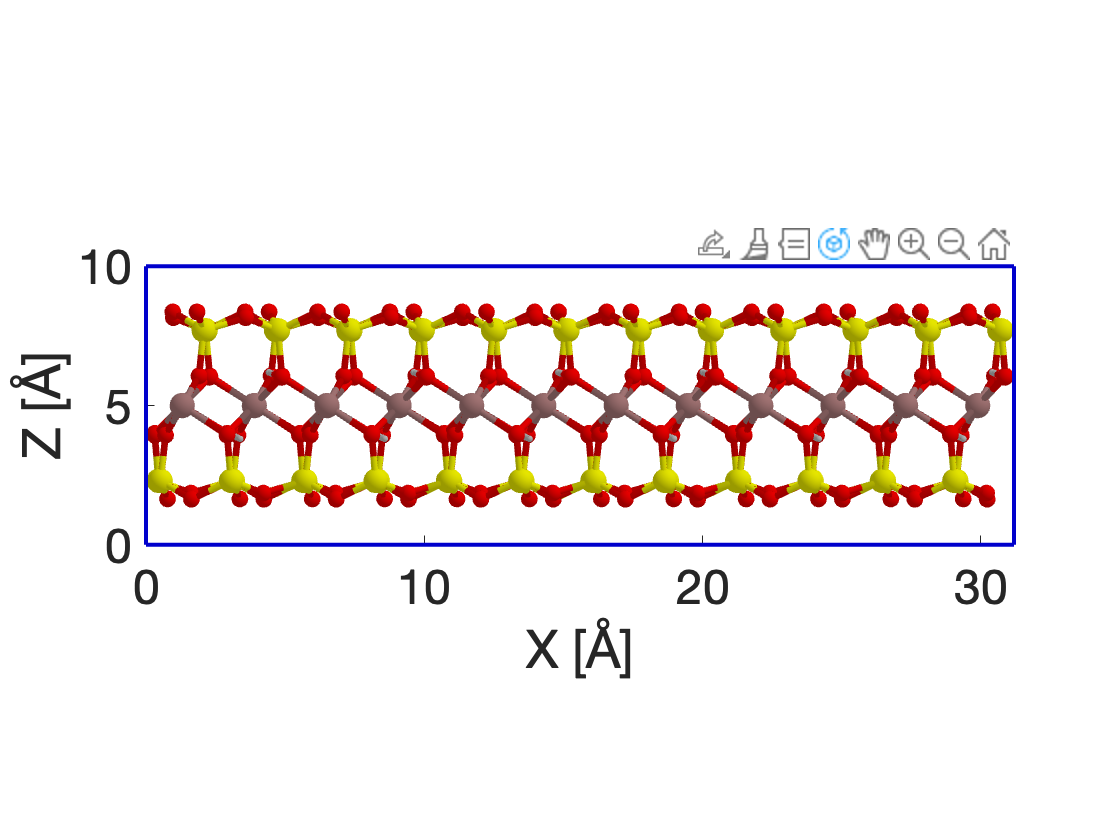

show_atom(atom,Box_dim);

%vmd(atom,Box_dim)

We can also center with respect to a certain resname group (here `'MMT'`)

close all;
atom=import_atom('6x4MMT_x10y5z0.gro');
atom=center_atom(atom,Box_dim,'MMT'); % Default 'all'
show_atom(atom,Box_dim);
%vmd(atom,Box_dim)

Or we can center with respect a certain x, y or z direction (here in the `'z'` direction)

close all;
atom=import_atom('6x4MMT_x10y5z0.gro');
atom=center_atom(atom,Box_dim,'MMT','z'); % Default 'xyz'
show_atom(atom,Box_dim);
%vmd(atom,Box_dim)